# Medium perturbation with unconstrained eGEM model

**Author**: Scott Campit

## Summary

This module computes metabolic fluxes for each demand reaction from the unconstrained eGEM model to evaluate how it performs without any other omics data imposed on it.

% Initialize metabolic modeling components
clear all;
initCobraToolbox; changeCobraSolver('gurobi', 'all');



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.25.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

## Load necessary variables and set necessary constraints

First let's load variables. The metabolic reconstruction map for the current version of the eGEM can be accessed using this [link](https://docs.google.com/spreadsheets/d/1skpEQaKxTmEci2XIzbMhtbDErk1qDaUup2bqHi0PYyc/edit?usp=sharing). 

Related files can be accessed using the hyperlinks below:

- Epigenome-scale metabolic model: [07082020.mat](https://drive.google.com/file/d/1cLt-_SzFccwABwnMjRnqaPl2DyNeyplu/view?usp=sharing)

- Nutrients and substrate uptake rates: [supplementary_software_code.mat](https://drive.google.com/file/d/1BAYiC6qZIeaPlLNrzrfFqLogH_TTUxeE/view?usp=sharing)

- Labels for nutrients: [unique_nutrients.mat](https://drive.google.com/file/d/1q2Y-9lhF22A_mKtYcfmmPY0I4stePxMK/view?usp=sharing)

load ~/Data/CBM/eGEM/07132020.mat;                               % Latest version of eGEM
load ~/Data/CBM/eGEM/ShenEtAl2019Supp.mat ...
         labels media_exchange1 mediareactions1; % Substrate uptake rates and exchange reaction names

% Set up objective function
eGEM.c = zeros(size(eGEM.c));
eGEM.c(string(eGEM.rxns) == 'biomass_objective') = 1;

% Update BiGG exchange reaction notation 
mediareactions1 = strrep(mediareactions1, '(', '_');
mediareactions1 = strrep(mediareactions1, ')', '');

#### Demand reactions to examine

I want to see how medium perturbation impacts flux through several demand reactions.

% Get list of demand reactions from eGEMM
pos = [3770, 3771, 3773:3777, 3780:3799];
dm_reactions = string(eGEM.rxns(pos))'

dm_reactions = 1×27 string array
    "DM_bulk_methylation"    "DM_bulk_acetylation"    "DM_KACn"    "DM_KACc"    "DM_KMe1"    "DM_KMe2"    "DM_KMe3"    "DM_h3k4me1_n"    "DM_h3k4me2_n"    "DM_h3k4me3_n"    "DM_h3k4ac1_n"    "DM_h3k9me1_n"    "DM_h3k9me2_n"    "DM_h3k9me3_n"    "DM_h3k9ac1_n"    "DM_h3k27me1_n"    "DM_h3k27me2_n"    "DM_h3k27me3_n"    "DM_h3k27ac1_n"    "DM_h3k36me1_n"    "DM_h3k36me2_n"    "DM_h3k36me3_n"    "DM_h3k36ac1_n"    "DM_h3k79me1_n"    "DM_h3k79me2_n"    "DM_h3k79me3_n"    "DM_h3k79ac1_n"


Let's turn off some specific reactions that cause trouble with metabolic models.

% Turn off specific reactions
posToTurnOff           = find(ismember(eGEM.rxns, {'ALR', 'MGSA', 'MGSA2'}));
eGEM.ub(posToTurnOff) = 0; eGEM.lb(posToTurnOff) = 0;

#### Methionine substrate uptake rate

Set methionine exchange to be really small, instead of default substrate uptake values from RECON1.

% Set methionine lower bound to a really small number
[~, pos] = ismember({'EX_met_L_e'}, eGEM.rxns);
eGEM.lb(pos) = -1.0;

Set the activity coefficient for demand reactions to be a fixed value, based on the medium perturbation experiments I ran with this current iteration of the eGEMM.

% Activity coefficient for demand reactions
epsilon_methylation = 0.069;
epsilon_acetylation = 1E-3;
for i = 1:length(dm_reactions)
    if contains(lower(dm_reactions(i)), "ac")
        epsilon(i, 1) = epsilon_acetylation;
    else
        epsilon(i, 1) = epsilon_methylation;
    end
end

#### Sample epsilon values

We'll also set the objective coefficient value for the demand reaction epsilon to be a really small number. Intially, I ran epsilons in the range of 1E-3 to 0.1, and found that there is no flux through methionine supplementation in histone reactions until we set epsilon to be 0.05. Further, some medium conditions result in no growth at epsilon = 0.1. Thus, I wanted to sample an arbitrary number of epsilon values in the range of [0.05, 0.1].

%load ~/Data/CBM/eGEM/epsilon/medium_epsilon.mat
%epsilon = double(epsilon_array(:, 2));

#### iMAT hyperparameters

Finally, let's set the parameters for the iMAT algorithm. No transcriptomics data was used to constrain the model. Additionally, parsimonious flux balance analysis was not implemented. 

% Params for constrain flux regulation. Set all to empty.
hyperparams.eps = []; hyperparams.isgenes = true;
hyperparams.kap = []; hyperparams.eps2 = [];
hyperparams.rho = []; hyperparams.pfba = false;
hyperparams.kap2 = [];

## Nutrient perturbation with the base metabolic model

These nested `for` loops computes the following metrics from medium supplementation and deprivation for each demand reaction:

- Metabolic fluxes

- Growth rates

- Nutrient shadow prices

- Reaction reduced costs

The final size of each matrix for any given epsilon value should be `50x44` for 50 nutrients by 44 demand reactions. Each matrix is stored as a cell corresponding to a given `epsilon` value.

% Metabolite shadow prices to catch
sp_positions = [2767, 2770:2806];
    
% Demand reaction layer
for r = 1:length(dm_reactions)
    [~, rxnPos] = ismember(dm_reactions(r), eGEM.rxns);
    
    % Supplementation / deprivation layer
    for kappatype = 1:2
        if kappatype == 1 % 1 = supplementation
            kappa  = 10; 
        else              % 2 = deprivation
            kappa = 0.01;
        end 
        
        % Nutrient perturbation layer
        for i = 1:50
            mod_kap = kappa;
            if (kappatype == 2) & (ismember(i,[2, 3, 5:19])) % Trace elements
                mod_kap = kappa / 100;
            elseif (kappatype == 1) & (ismember(i, [1;4]))   % Glucose / Glutamine
                mod_kap = 3;
            end
            
            % Add activity to demand reactions
            tmp = eGEM;
            tmp.c(rxnPos) = epsilon(r);
            
            % Modify uptake rate based on supplementation or deprivation
            [~, pos]  = ismember(mediareactions1(i), tmp.rxns);
            tmp.lb(pos) = -media_exchange1(i, 1) * mod_kap;
    
            % Linear optimization to get flux and growth rate
            [~, solution] = CFR(tmp, hyperparams, {}, {});
            
            % Save flux and growth rate based on supplementation / deprivation
            if kappatype == 1
                supplementation_grate(i, r) = solution.x(3743);
            else
                deprivation_grate(i, r) = solution.x(3743);
            end
            
            tmp2 = tmp;
            
            % Modify uptake rate based on supplementation or deprivation
            [~, pos]  = ismember(mediareactions1(i), tmp2.rxns);
            tmp2.lb(pos) = -media_exchange1(i, 1) * mod_kap;
            tmp2.lb(3743) = solution.x(3743) * 0.99;
            tmp2.c(3743)  = 0;                                                
            [~, solution] = CFR(tmp2, hyperparams, {}, {});
            
            % Save metabolic flux, reduced cost, and shadow price based on supplementation / deprivation
            if kappatype == 1
                supplementation_flux(i, r)  = solution.x(rxnPos);
                supplementation_rc(i, r)    = solution.rc(rxnPos);
                supplementation_sp(i, r, :) = solution.pi(sp_positions);
            else
                deprivation_flux(i, r)  = solution.x(rxnPos);
                deprivation_rc(i, r)        = solution.rc(rxnPos);
                deprivation_sp(i, r, :)     = solution.pi(sp_positions);
            end
        end
    end
end

## Visualize the results from nutrient supplementation and deprivation using heatmaps

Base on the previous analysis, it turns out that an `epsilon` value of 0.0625 is optimal to balance flux going through demand reactions while allowing cells to have a non-zero growth rate. The values are stored in the 4th index of the cell array (`).`

We'll make the redbluecmap continuous.

% Colormap
redbluecmap = imresize(redbluecmap, [1000, 3]); 
redbluecmap = min(max(redbluecmap, 0), 1);

Next, we'll set up the labels for the axes

% Set labels
dm_labels = strrep(dm_reactions, '_', ' ');
dm_labels = strrep(dm_labels, 'DM', '');

load ~/Data/unique_nutrients.mat
medium = labels;

We'll set fluxes that are equal to 0 to be NaN for visualization purposes.

% Make some reactions black for none
supplementation_flux(supplementation_flux == 0)             = NaN; 
supplementation_grate(supplementation_grate == 0)           = NaN;
deprivation_flux(deprivation_flux == 0)                     = NaN;         
deprivation_grate(deprivation_grate == 0)                   = NaN;

### Metabolic flux heatmap

Finally, we can construct the two heatmaps side-by-side, where the left one is nutrient supplementation and the right one is nutrient deprivation.

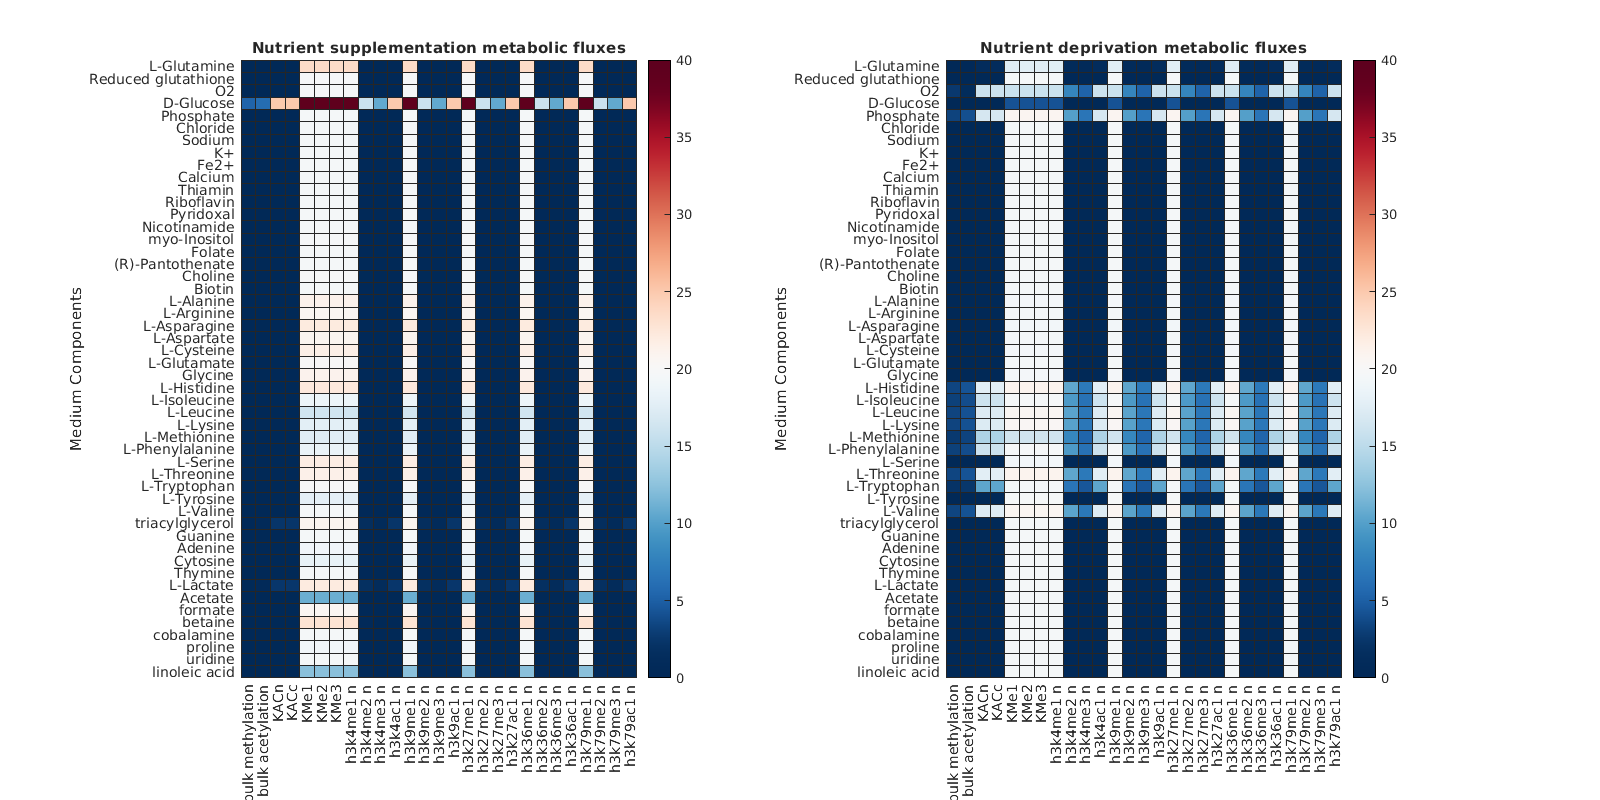

figure;
% Nutrient supplementation heatmap
subplot(1, 2, 1);
ax1 = heatmap(supplementation_flux, ...
        'YData', medium, ...
        'XData', dm_labels', ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient supplementation metabolic fluxes', ...
        'FontSize', 10, ...
        'FontName', 'Helvetica');
    
caxis(ax1, [0 40]);

% Nutrient deprivation heatmap 
subplot(1, 2, 2);
ax2 = heatmap(deprivation_flux, ...
        'YData', medium, ...
        'XData', dm_labels', ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient deprivation metabolic fluxes', ...
        'FontSize', 10, ...
        'FontName', 'Helvetica');
caxis(ax2, [0 40]);
    
set(gcf,'position',[0, 0, 1600, 800]);

#### Visualized metabolic fluxes normalized by the growth rate

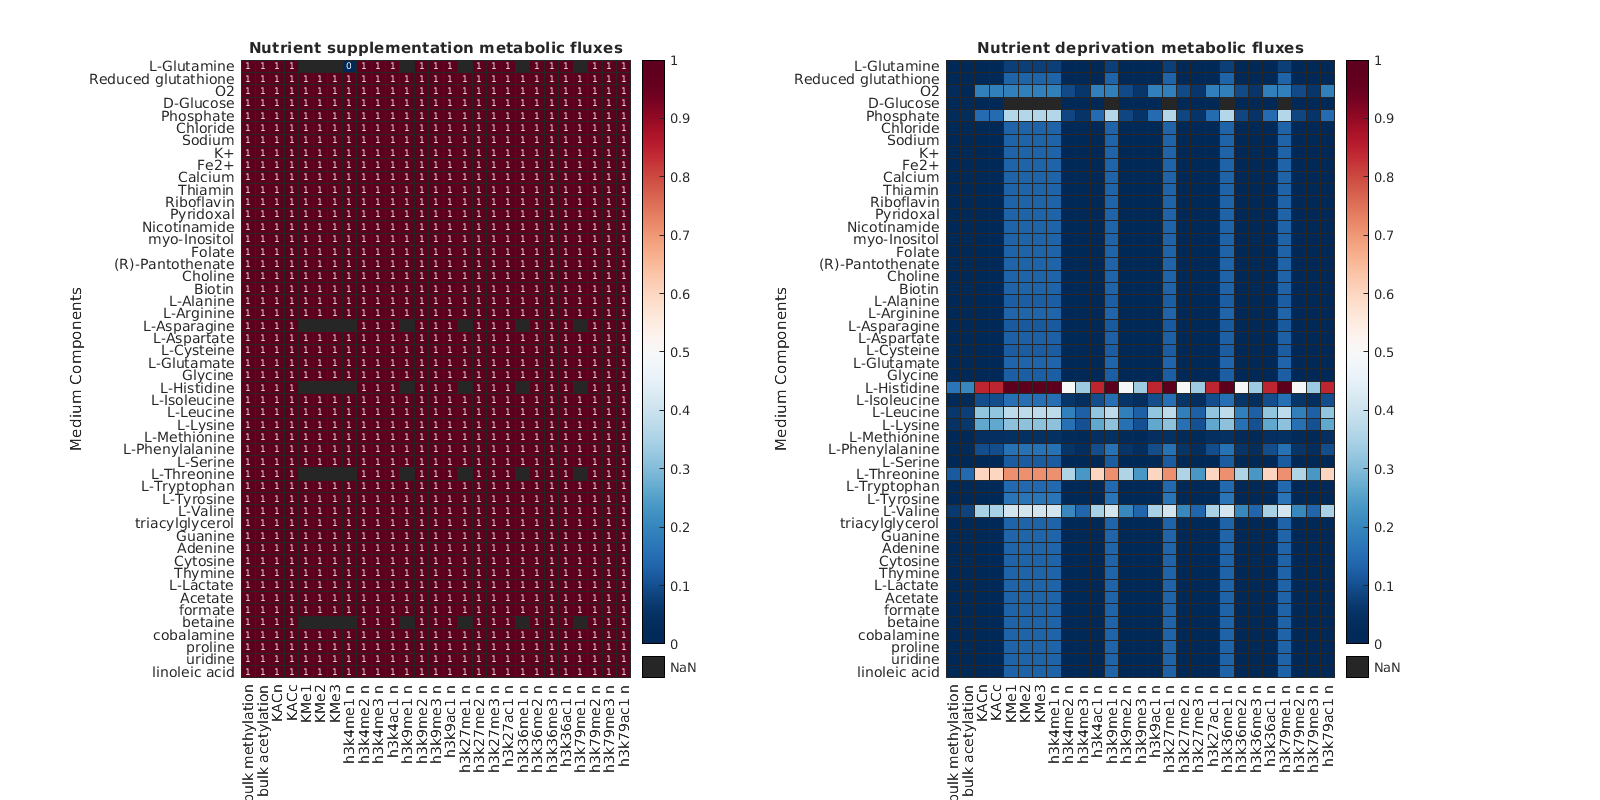

figure;
% Nutrient supplementation heatmap
subplot(1, 2, 1);
heatmap(rescale(supplementation_flux ./ supplementation_grate), ...
        'YData', medium, ...
        'XData', dm_labels', ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient supplementation metabolic fluxes', ...
        'FontSize', 10, ...
        'FontName', 'Helvetica');

% Nutrient deprivation heatmap 
subplot(1, 2, 2);
heatmap(rescale(deprivation_flux ./ deprivation_grate), ...
        'YData', medium, ...
        'XData', dm_labels', ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient deprivation metabolic fluxes', ...
        'FontSize', 10, ...
        'FontName', 'Helvetica');
set(gcf,'position',[0, 0, 1600, 800]);

### Growth rate heatmap

Finally, we can construct the two heatmaps side-by-side, where the left one is nutrient supplementation and the right one is nutrient deprivation.

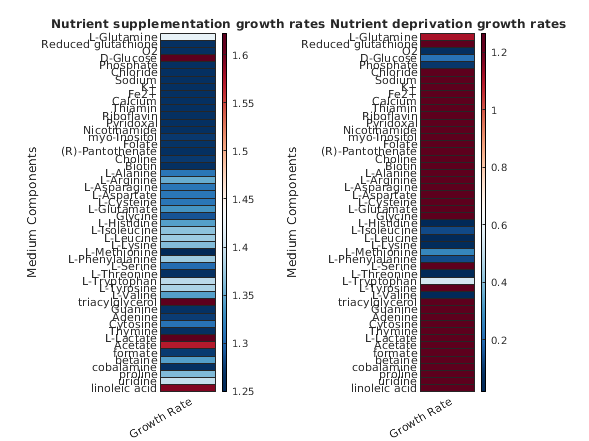

figure;
% Nutrient supplementation heatmap
subplot(1, 2, 1);
heatmap(supplementation_grate(:, 1), ...
        'YData', medium, ...
        'XData', ['Growth Rate'], ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient supplementation growth rates', ...
        'FontSize', 8, ...
        'FontName', 'Helvetica');

% Nutrient deprivation heatmap 
subplot(1, 2, 2);
heatmap(deprivation_grate(:, 1), ...
        'YData', medium, ...
        'XData', ['Growth Rate'], ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient deprivation growth rates', ...
        'FontSize', 8, ...
        'FontName', 'Helvetica');

## Reduced cost heatmap

% Remove peplys demand reaction
supplementation_rc(:, peplys_pos) = []; deprivation_rc(:, peplys_pos) = [];     

Unrecognized function or variable 'peplys_pos'.

We'll set fluxes that are equal to 0 to be NaN for visualization purposes.

% Make some reactions black for none
supplementation_rc(supplementation_rc == 0) = NaN; 
deprivation_rc(deprivation_rc == 0)         = NaN;  

Visualize the reduced cost

figure;
% Nutrient supplementation heatmap
subplot(1, 2, 1);
heatmap(supplementation_rc, ...
        'YData', medium, ...
        'XData', dm_labels', ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient supplementation metabolic fluxes', ...
        'FontSize', 10, ...
        'FontName', 'Helvetica');

% Nutrient deprivation heatmap 
subplot(1, 2, 2);
heatmap(deprivation_rc, ...
        'YData', medium, ...
        'XData', dm_labels', ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient deprivation metabolic fluxes', ...
        'FontSize', 10, ...
        'FontName', 'Helvetica');
set(gcf,'position',[0, 0, 1600, 800]);